%% demo_03_semantic_topic_map : Pipeline standard JSONL -> text -> MiniLM embedding (NO reduction/clustering yet)
% Step1-4 only (up to embeddings)

clear; clc;

% Robust repoRoot resolution for Live Script
mlxPath = matlab.desktop.editor.getActiveFilename();
assert(strlength(mlxPath) > 0, "Cannot resolve active file path. Open this .mlx in the Editor and run it.");
examplesDir = fileparts(mlxPath);
repoRoot    = fileparts(examplesDir);
addpath(genpath(fullfile(repoRoot,"src")));
rehash;

% Explicitly provide HubRoot for bootstrap
hubRoot = repoRoot;             % this repo is the hub
% Bootstrap: define this repo as the OpenAlex hub (once)
hubRoot = repoRoot;  % this repository is the hub root
setenv("OPENALEX_MATLAB_HUB", hubRoot);

cfg = topicmap.setup("HubRoot", hubRoot);
cfg = topicmap.env_check(cfg);

[topicmap.env_check] WARN (2):
  - Pipeline repo not found (expected <hub>/matlab-openalex-pipeline/src). End-to-end fetch will be unavailable.
  - Normalize repo not found (expected <hub>/matlab-openalex-normalize/src). This is OK for demo_02 (JSONL->map).
[topicmap.env_check] NEXT (4):
  * Clone matlab-openalex-pipeline under hubRoot and re-run topicmap.env_check().
  * For demo_02: set cfg.input.pipelineJsonl to a pipeline output JSONL (works JSONL).
  * Optional: clone matlab-openalex-normalize only if you want CSV-based workflows.
  * Optional: set cfg.sample.worksCsv to support a CSV-based minimal demo (demo_01).


% ---- run output folder ----
cfg.runDir = topicmap.make_run_dir(cfg, "demo03");

% ---- 1) choose input JSONL (priority: cfg.input.pipelineJsonl -> data_sample/*.standard.jsonl) ----
jsonlPath = "";
if isfield(cfg,"input") && isfield(cfg.input,"pipelineJsonl") && strlength(string(cfg.input.pipelineJsonl))>0
    jsonlPath = string(cfg.input.pipelineJsonl);
end
if strlength(jsonlPath)==0
    d = dir(fullfile(cfg.repoRoot, "data_sample", "*.standard.jsonl"));
    assert(~isempty(d), "No *.standard.jsonl found under data_sample/. Set cfg.input.pipelineJsonl.");
    [~, idxNewest] = max([d.datenum]); % newest sample
    jsonlPath = fullfile(d(idxNewest).folder, d(idxNewest).name);
end
assert(isfile(jsonlPath), "JSONL not found: %s", jsonlPath);
fprintf("Using JSONL: %s\n", jsonlPath);

Using JSONL: D:\workspace\github\openalex-topic-map\data_sample\openalex_MATLAB_cursor_en_1000.standard.jsonl



% ---- 2) load works ----
W = topicmap.read_pipeline_jsonl(jsonlPath);

% ---- 3) build text (title+abstract) ----
policy  = "title+abstract";
maxChars = 6000;
if isfield(cfg,"text") && isstruct(cfg.text)
    if isfield(cfg.text,"policy")   && strlength(string(cfg.text.policy))>0
        policy = string(cfg.text.policy);
    end
    if isfield(cfg.text,"maxChars") && ~isempty(cfg.text.maxChars)
        maxChars = cfg.text.maxChars;
    end
end

[text, meta] = topicmap.extract_text(W, policy, maxChars);
text = arrayfun(@topicmap.clean_text, text);

% drop empties
keep = strlength(text) > 0;
text = text(keep);
meta.work_id = meta.work_id(keep);
meta.title   = meta.title(keep);
meta.abstract= meta.abstract(keep);
meta.year    = meta.year(keep);

fprintf("Loaded %d works (non-empty text: %d)\n", numel(W), numel(text));

Loaded 1000 works (non-empty text: 1000)



% ---- 4) Transformer embeddings (MiniLM-L6-v2 via documentEmbedding) ----
% Requirement: Add-On "Text Analytics Toolbox Model for all-MiniLM-L6-v2 Network"
% Already checked in env_check, but keep this assert for direct script usage.
assert(isfield(cfg,"env") && isfield(cfg.env,"optionalOk_demo03") && cfg.env.optionalOk_demo03, ...
    "demo03 prerequisites not met. Run topicmap.env_check() and install MiniLM-L6-v2 Add-On.");

rng(cfg.seed);

fprintf("Initializing documentEmbedding model: all-MiniLM-L6-v2 ...\n");

Initializing documentEmbedding model: all-MiniLM-L6-v2 ...


emb = documentEmbedding(Model="all-MiniLM-L6-v2");

% Embed in batches to avoid memory spikes (safe default)
batchSize = 128;
if isfield(cfg,"demo03") && isfield(cfg.demo03,"batchSize") && ~isempty(cfg.demo03.batchSize)
    batchSize = cfg.demo03.batchSize;
end

n = numel(text);
E = [];  % will allocate after first batch (dimension depends on model)
fprintf("Embedding %d documents (batchSize=%d)...\n", n, batchSize);

Embedding 1000 documents (batchSize=128)...



tStart = tic;
for i0 = 1:batchSize:n
    i1 = min(n, i0 + batchSize - 1);
    tb = text(i0:i1);

    Eb = embed(emb, tb);  % returns (nb x D)
    if isempty(E)
        % Preallocate as single for disk/memory efficiency
        D = size(Eb, 2);
        E = zeros(n, D, "single");
    end
    E(i0:i1, :) = single(Eb);

    if mod(i0, batchSize*10) == 1 || i1 == n
        fprintf("  embedded %d/%d\n", i1, n);
    end
end

  embedded 128/1000
  embedded 1000/1000


fprintf("Embedding done. Elapsed: %.1fs\n", toc(tStart));

Embedding done. Elapsed: 4.7s



% ---- 4b) save outputs into runDir ----
% Save embeddings + essential metadata
outMat = fullfile(cfg.runDir, "demo03_embeddings.mat");
save(outMat, "E", "meta", "jsonlPath", "policy", "maxChars", "batchSize", "-v7.3");
fprintf("Wrote: %s\n", outMat);

Wrote: D:\workspace\github\openalex-topic-map\data_processed\openalex-topicmap\20251223_223848_demo03\demo03_embeddings.mat



% Save meta as CSV for quick inspection / joins
T_meta = table(string(meta.work_id), double(meta.year), string(meta.title), ...
    'VariableNames', {'work_id','year','title'});
outMetaCsv = fullfile(cfg.runDir, "demo03_embeddings_meta.csv");
writetable(T_meta, outMetaCsv);
fprintf("Wrote: %s\n", outMetaCsv);

Wrote: D:\workspace\github\openalex-topic-map\data_processed\openalex-topicmap\20251223_223848_demo03\demo03_embeddings_meta.csv



% Optional: lightweight sanity check
fprintf("E size: %d x %d\n", size(E,1), size(E,2));

E size: 1000 x 384


fprintf("Next: PCA->UMAP, kmeans, representatives (Step5+)\n");

Next: PCA->UMAP, kmeans, representatives (Step5+)


%% Step 5: Dimensionality reduction (PCA -> 2D)
% We reduce embeddings for visualization only.
% Clustering / representatives are based on the original embedding space E.

% Parameters (fixed defaults for reproducibility)
K = 12;       % kmeans clusters (coarse, fixed)
repN = 3;     % representative papers per cluster
pcaDims = 50; % intermediate PCA dims for stable 2D embedding

if isfield(cfg,"demo03") && isstruct(cfg.demo03)
    if isfield(cfg.demo03,"K") && ~isempty(cfg.demo03.K), K = cfg.demo03.K; end
    if isfield(cfg.demo03,"repN") && ~isempty(cfg.demo03.repN), repN = cfg.demo03.repN; end
    if isfield(cfg.demo03,"pcaDims") && ~isempty(cfg.demo03.pcaDims), pcaDims = cfg.demo03.pcaDims; end
end

% PCA
fprintf("Running PCA -> %d dims...\n", pcaDims);

Running PCA -> 50 dims...


[~, Zpca] = pca(double(E), "NumComponents", pcaDims);

% 2D embedding: prefer UMAP if available, otherwise fall back to t-SNE.
% (UMAP may be provided either by MATLAB built-in 'umap' or FileExchange 'run_umap'.)
fprintf("Computing 2D embedding...\n");

Computing 2D embedding...


U2 = [];
embedMethod = "";

% R2025b+: Java Swing access to figures is withdrawn, so run_umap must not touch GUI.
% Use 'verbose' = 'none' (or 'text') explicitly to avoid Swing/figure usage.
umapVerbose = "none";
if isfield(cfg,"demo03") && isstruct(cfg.demo03) && isfield(cfg.demo03,"umapVerbose") ...
        && strlength(string(cfg.demo03.umapVerbose))>0
    umapVerbose = string(cfg.demo03.umapVerbose);
end

if exist("umap","file") ~= 0
    % Newer MATLAB versions may provide umap()
    try
        % Signature varies across versions; keep it conservative
        U2 = umap(Zpca, "Metric", "cosine", "NumDimensions", 2, "RandomState", cfg.seed);
        embedMethod = "UMAP";
    catch
        U2 = [];
    end
end

if isempty(U2) && exist("run_umap","file") ~= 0
    % File Exchange run_umap
    try
        [U2, ~, ~, ~] = run_umap(Zpca, ...
            "n_components", 2, ...
            "metric", "cosine", ...
            "n_neighbors", 15, ...
            "min_dist", 0.1, ...
            "random_state", cfg.seed, ...
            "verbose", umapVerbose);
        embedMethod = "UMAP(run_umap)";
    catch
        U2 = [];
    end
end

if isempty(U2)
    % Built-in fallback (widely available): t-SNE
    if exist("tsne","file") == 0
        error("No 2D embedding method found. Install/run UMAP (umap or run_umap) or ensure tsne is available.");
    end
    U2 = tsne(Zpca, ...
        "Algorithm", "barneshut", ...
        "Distance", "cosine", ...
        "NumDimensions", 2, ...
        "Standardize", true, ...
        "Perplexity", 30, ...
        "Verbose", 0);
    embedMethod = "t-SNE";
end

fprintf("2D embedding done using %s. U2 size: %d x %d\n", embedMethod, size(U2,1), size(U2,2));

2D embedding done using UMAP(run_umap). U2 size: 1000 x 2



%% Step 6: Clustering (kmeans in embedding-derived 2D for stability)
% Cluster assignment is based on U2 for a simple baseline. (HDBSCAN comes later in demo04.)
fprintf("Clustering with kmeans (K=%d)...\n", K);

Clustering with kmeans (K=12)...


rng(cfg.seed);
idx = kmeans(U2, K, ...
    "Distance", "sqeuclidean", ...
    "Replicates", 10, ...
    "MaxIter", 500, ...
    "Display", "off");

%% Step 7: Representative papers per cluster (based on embedding space E, cosine distance)
% Representatives are chosen in the ORIGINAL embedding space (not U2).
fprintf("Selecting representatives (repN=%d) in embedding space...\n", repN);

Selecting representatives (repN=3) in embedding space...



Eunit = single(E);
Eunit = Eunit ./ max(vecnorm(Eunit, 2, 2), eps("single")); % normalize rows

repRows = [];
repCluster = [];
repRank = [];
repScore = [];

for c = 1:K
    members = find(idx == c);
    if isempty(members), continue; end
    mu = mean(Eunit(members, :), 1);
    mu = mu ./ max(norm(mu), eps("single"));

    % cosine distance = 1 - cosine similarity
    cosSim = Eunit(members, :) * mu';
    dist = 1 - cosSim;

    [distSorted, ord] = sort(dist, "ascend");
    take = min(repN, numel(ord));
    picked = members(ord(1:take));

    repRows = [repRows; picked(:)];
    repCluster = [repCluster; repmat(c, take, 1)];
    repRank = [repRank; (1:take)'];
    repScore = [repScore; distSorted(1:take)];
end

work_id = string(meta.work_id(repRows)); work_id = work_id(:);
year    = double(meta.year(repRows));    year    = year(:);
paper_title = string(meta.title(repRows)); paper_title = paper_title(:);
cluster = repCluster(:);
rank    = repRank(:);
score   = repScore(:);
x       = U2(repRows,1); x = x(:);
y       = U2(repRows,2); y = y(:);

T_rep = table(cluster, rank, work_id, year, paper_title, score, x, y, ...
    'VariableNames', {'cluster','rank','work_id','year','title','cosine_distance','x','y'});

outRepCsv = fullfile(cfg.runDir, "demo03_cluster_representatives.csv");
writetable(T_rep, outRepCsv);
fprintf("Wrote: %s\n", outRepCsv);

Wrote: D:\workspace\github\openalex-topic-map\data_processed\openalex-topicmap\20251223_223848_demo03\demo03_cluster_representatives.csv



% Save 2D coords + cluster assignment (normalize shapes + use legacy VariableNames syntax)
work_id_all = string(meta.work_id); work_id_all = work_id_all(:);
year_all    = double(meta.year);    year_all    = year_all(:);
x_all       = U2(:,1);              x_all       = x_all(:);
y_all       = U2(:,2);              y_all       = y_all(:);
cluster_all = idx;                  cluster_all = cluster_all(:);

% defensive assert
H2 = [numel(work_id_all) numel(year_all) numel(x_all) numel(y_all) numel(cluster_all)];
assert(all(H2==H2(1)), "U2 table column height mismatch: %s", mat2str(H2));

T_u2 = table(work_id_all, year_all, x_all, y_all, cluster_all, ...
    'VariableNames', {'work_id','year','x','y','cluster'});
outU2Csv = fullfile(cfg.runDir, "demo03_umap2d.csv");
writetable(T_u2, outU2Csv);
fprintf("Wrote: %s\n", outU2Csv);

Wrote: D:\workspace\github\openalex-topic-map\data_processed\openalex-topicmap\20251223_223848_demo03\demo03_umap2d.csv


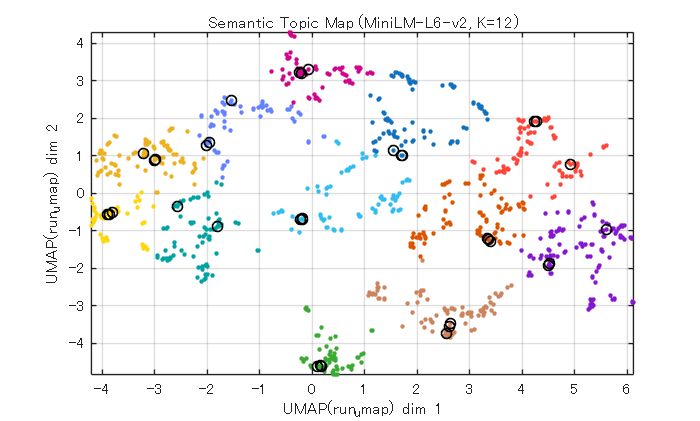


%% Figure (academic-ish)
f = figure("Name","demo_03 Semantic Topic Map", "Color","w");
ax = axes(f);
hold(ax, "on");

% plot all points
gscatter(ax, U2(:,1), U2(:,2), idx, [], ".", 8, "off");
grid(ax, "on");
box(ax, "on");
axis(ax, "tight");
ax.XLabel.String = sprintf("%s dim 1", embedMethod);
ax.YLabel.String = sprintf("%s dim 2", embedMethod);
ax.Title.String  = sprintf("Semantic Topic Map (MiniLM-L6-v2, K=%d)", K);

% highlight representatives
plot(ax, T_rep.x, T_rep.y, "ko", "MarkerSize", 6, "LineWidth", 1);

% export
outPdf = fullfile(cfg.runDir, "demo03_map.pdf");
outPng = fullfile(cfg.runDir, "demo03_map.png");
exportgraphics(f, outPdf, "ContentType","vector");
exportgraphics(f, outPng, "Resolution", 300);

fprintf("Wrote: %s\nWrote: %s\n", outPdf, outPng);

Wrote: D:\workspace\github\openalex-topic-map\data_processed\openalex-topicmap\20251223_223848_demo03\demo03_map.pdf
Wrote: D:\workspace\github\openalex-topic-map\data_processed\openalex-topicmap\20251223_223848_demo03\demo03_map.png



fprintf("demo03 Step5-7 complete.\n");

demo03 Step5-7 complete.
